**Execute a command**

- Try writing a command in command window 

- Assign a variable : Assign a constant to variable 

- Assignment operator : The operator(=) can be used to assign value

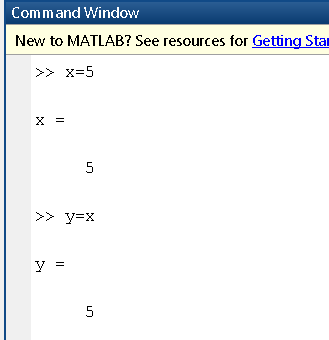

x=5

x =      5


y=x

y =      5


**Workspace in matlab**

It contains the current variables that are stored 

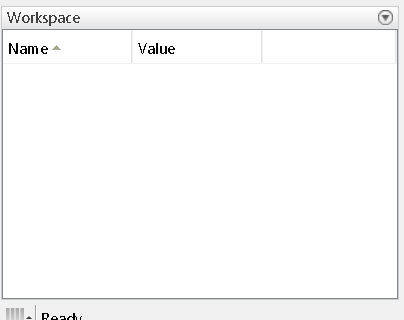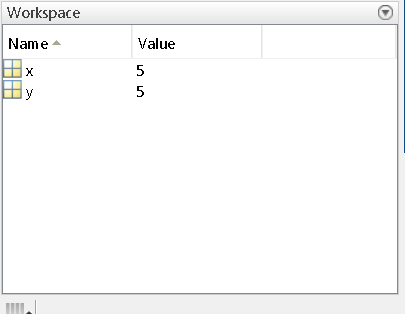

**Semicolon** 

Using a semicolon after any operation does not print the output 

**Recall previous commands**

By using arrow keys we can also refer to previous commands entered in command window

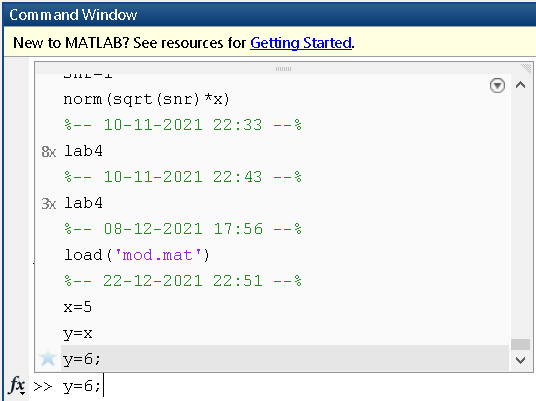

**Enter just a variable**

writing a varibale and simply pressing enter prints its value

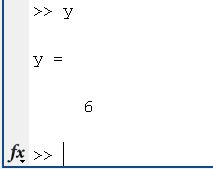

**Naming a Variable**

You can name your Matlab Variables anything start wih a letter and contain only letters , numbers and underscores (_)

y=6;
y

y =      6


**Save the workspace to a mat file** 

We can save the current workspace to be loaded again in future . This saves the data to .mat file in the current directory .

Simply,

save filename

load filename

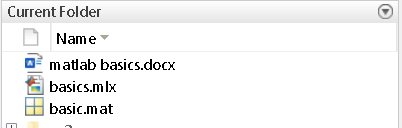

Side tip : To remove previous clear the command window use "clc"

save basic.mat
load basic.mat

**Using built in functions**

Matlab has a lot of built in functions that can be used to perform operations 

abs , sin , cos , sqrt 

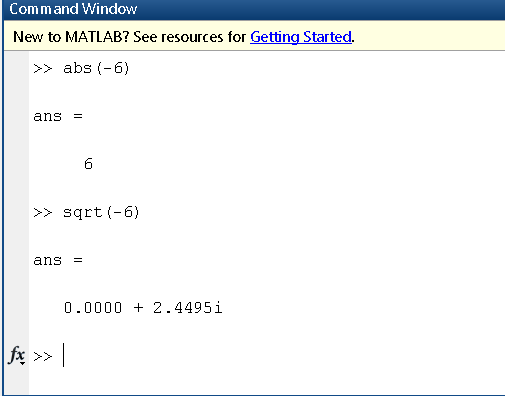

While performing an operation you might have noticed that the output shows only 4 decimal digits to increase/decrease the accuracy of operations we use 

 format long , format short

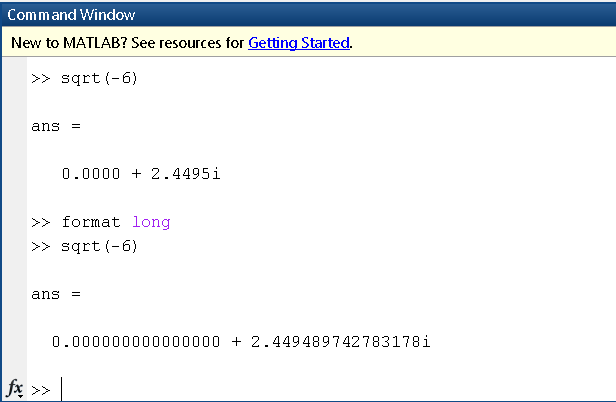

abs(-6)

ans =      6


sqrt(-6)

ans =   0.000000000000000 + 2.449489742783178i


format long 
sqrt(-6)

ans =   0.000000000000000 + 2.449489742783178i


**Array **

Collection of data is called an array . It has two constituents rows and columns

array=[(row1,col1) (row1,col2) (row1,col3);

            (row2,col1) (row2,col2) (row2,col3);

            (row2,col1) (row3,col2) (row3,col3)]

A column array of size [rows cols]=[1 2]

x=[1 2] 

To make rows semicolon is used.[rows cols]=[2 1]

x=[1;2]

Example

x = [3 4 5;6 7 8]

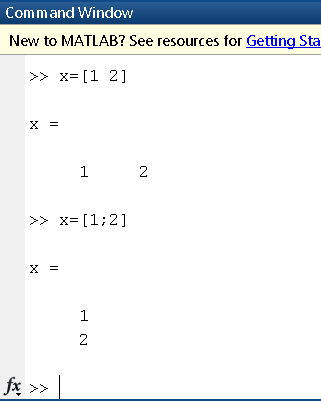

x=[1 2]

x =      1     2


x=[1;2]

x =      1
     2


x=[3 4 5;6 7 8]

x =      3     4     5
     6     7     8


**Vector**

A **vector** is a list of numbers (can be in a row or column)

Evently Spaced vectors

To make a list of vectors we use a **first:last** , by default the difference is 1.

y=5:8

We can also use the following format **first:difference:last**

x=20:2:26

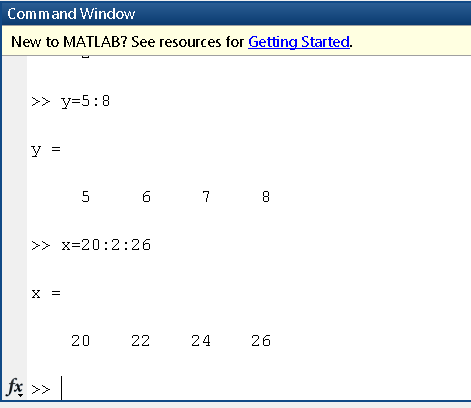

If we know the number of elements we require we can use the following command **linspace(*****first*****,*****last*****,*****number_of_elements*****)**

linspace(1,10,100)

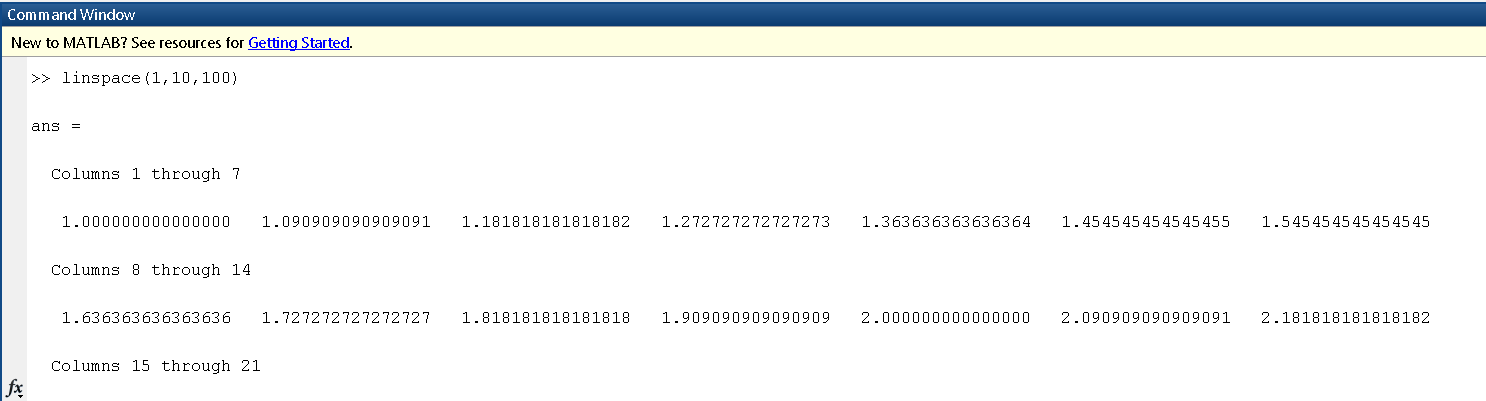

Exercise : If we want to make a 100 elements between 1 and 2*pi what command should we use

Note : The output of these commands results in a column vector , to convert it into a row vector we can do Transpose by

**x=x’**

Side tip: If you dont assign a variable to the output it is stored in ans

y=5:8

x =   -1.570796326794897  -1.470796326794896  -1.370796326794897  -1.270796326794897  -1.170796326794897  -1.070796326794897  -0.970796326794896  -0.870796326794896  -0.770796326794897  -0.670796326794897  -0.570796326794897  -0.470796326794896  -0.370796326794896  -0.270796326794897  -0.170796326794896  -0.070796326794897   0.029203673205104   0.129203673205103   0.229203673205103   0.329203673205103   0.429203673205103   0.529203673205104   0.629203673205104   0.729203673205103   0.829203673205103   0.929203673205103   1.029203673205104   1.129203673205104   1.229203673205103   1.329203673205104   1.429203673205103   1.529203673205104


x=20:2:26

y =    0.000000000000000   0.099833416646828   0.198669330795061   0.295520206661340   0.389418342308650   0.479425538604203   0.564642473395035   0.644217687237691   0.717356090899523   0.783326909627483   0.841470984807897   0.891207360061435   0.932039085967226   0.963558185417193   0.985449729988460   0.997494986604054   0.999573603041505   0.991664810452469   0.973847630878195   0.946300087687414   0.909297426825682   0.863209366648874   0.808496403819590   0.745705212176720   0.675463180551151   0.598472144103956   0.515501371821464   0.427379880233830   0.334988150155905   0.239249329213982   0.141120008059867   0.041580662433290


linspace(1,10,100)

z =   -1.000000000000000  -0.995004165278026  -0.980066577841242  -0.955336489125606  -0.921060994002885  -0.877582561890373  -0.825335614909678  -0.764842187284488  -0.696706709347165  -0.621609968270664  -0.540302305868140  -0.453596121425577  -0.362357754476673  -0.267498828624587  -0.169967142900241  -0.070737201667703   0.029199522301289   0.128844494295525   0.227202094693087   0.323289566863503   0.416146836547142   0.504846104599858   0.588501117255346   0.666276021279824   0.737393715541246   0.801143615546934   0.856888753368947   0.904072142017061   0.942222340668658   0.970958165149591   0.989992496600445   0.999135150273279


x=x'

**Array Creation Functions**

Some arrays which are widely used during calculations have pre defined functions

Make a 2x2 random number array between 0 and 1

x = rand(2)

Make a 2x3 random number array between 0 and 1

x = rand(2,3)

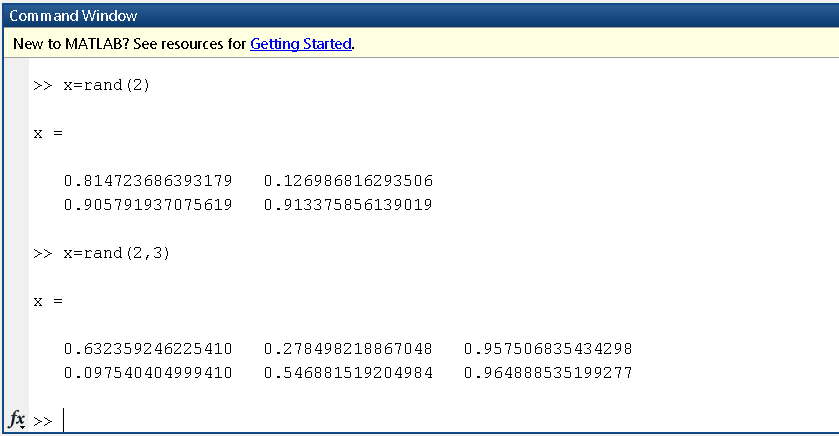

Make an array of ones 

ones(2,3)

Similarily try  zeros,eye

Tip : size , can be used to get the size of an array

x=rand(2)
x=rand(2,3)
size(x)

**Indexing an array**

To refer to an element in array indexing is used 

Index an element : x(1)

For a 2D it reads column wise i.e for a 2x3 array

1 3 5

2 4 6

Index series of element : x(2:4) , elemts from index 2 to 4 are given as output

Index 2D array : x(1,:) , all elements in row=1 and all columns are given as output 

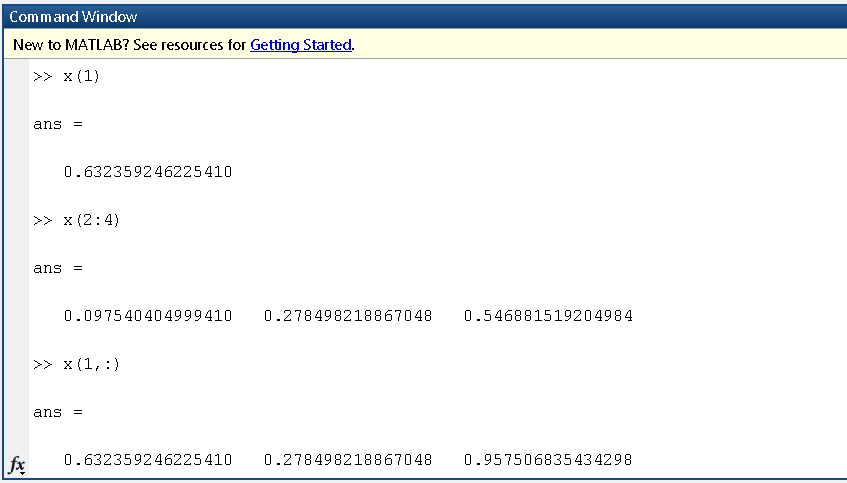

So, x(idx) , x(row,col)

Indexing the last element : z=x(end,2) or x(end-1,2)

Exercise : Try extracting the non consecutive numbers in array

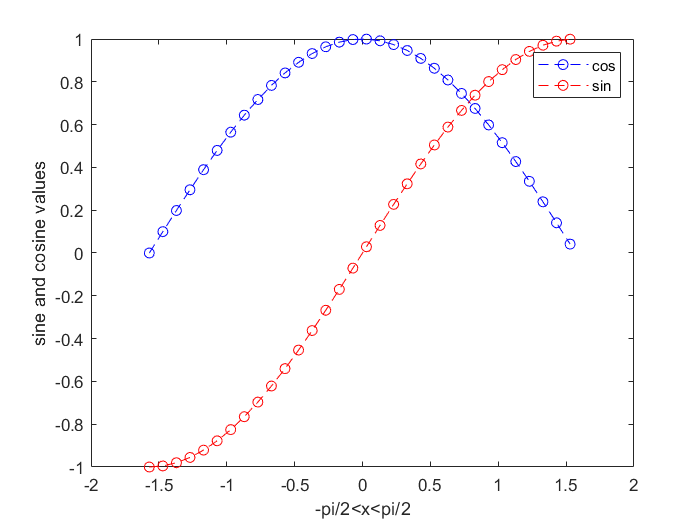

x(1)
x(2:4)
x(1,:)

z=x(end,2)
y(1)=x(end,2)

**Arithmetic Operations**

x=[1 2 3 4]

y=x+2

z=x+y

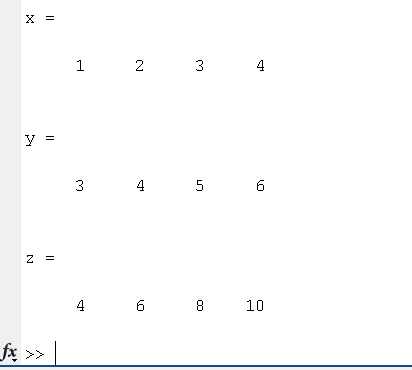

basic statistic max,sqrt,matrix multiplication are all applicable on arrays

For Matrix multiplication , z=[3 4] *[10;20]

For element wise multiplication , z=[3 4] .*[10 20]

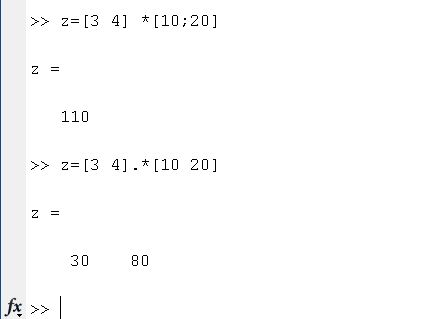

The dot before a mathematical opration implies element wise operation

Example: x=x.^2

                x=x^2

x=[1 2 3 4]
y=x+2
z=x+y
z=[3 4] *[10;20]
z=[3 4].*[10 20]

**Function calls**

x=[1 2 3 4 5]

[xrow,xcol] = size(x)

The output of size is assigned to xrow and xcol variables

[xMax,idx] = max(x)

Use tilde to ignore specific values

[~,ivMax] = max(x)

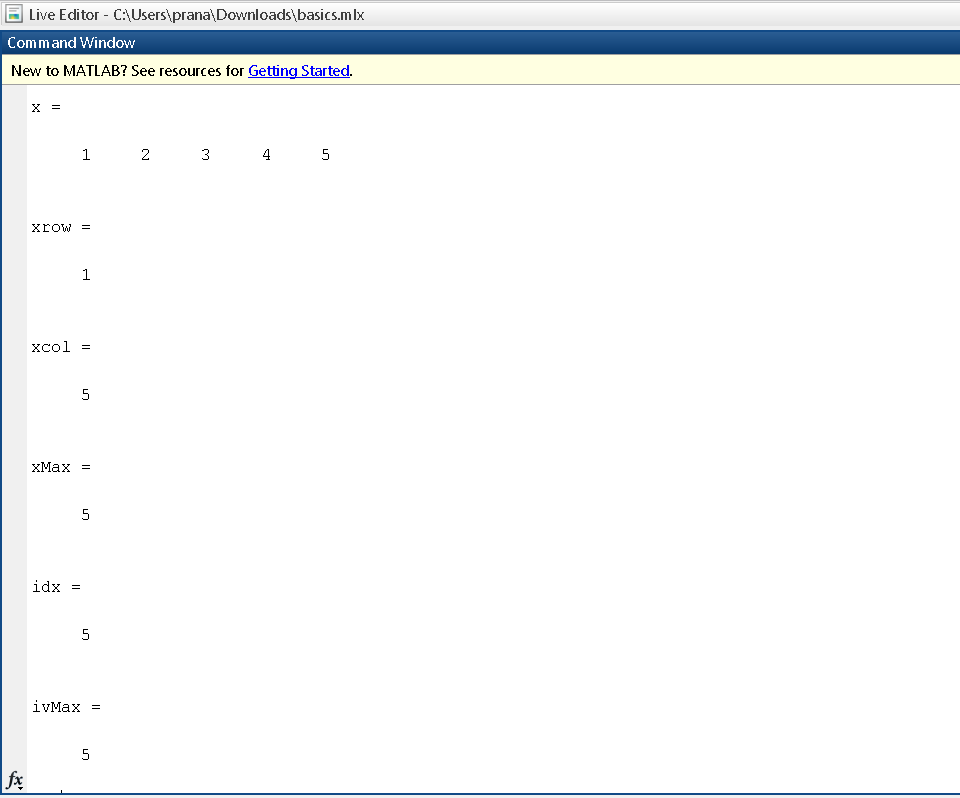

Exercise : Check the documentation for creating a custom function [https://in.mathworks.com/help/matlab/ref/function.html](https://in.mathworks.com/help/matlab/ref/function.html) 

x=[1 2 3 4 5]
[xrow,xcol] = size(x)
[xMax,idx] = max(x)
[~,ivMax] = max(x)

**Obtaing Help from matlab documentation**

We cant remember everything so matlab has offline documentation of everything that is required . Click on Help or search in documentation.

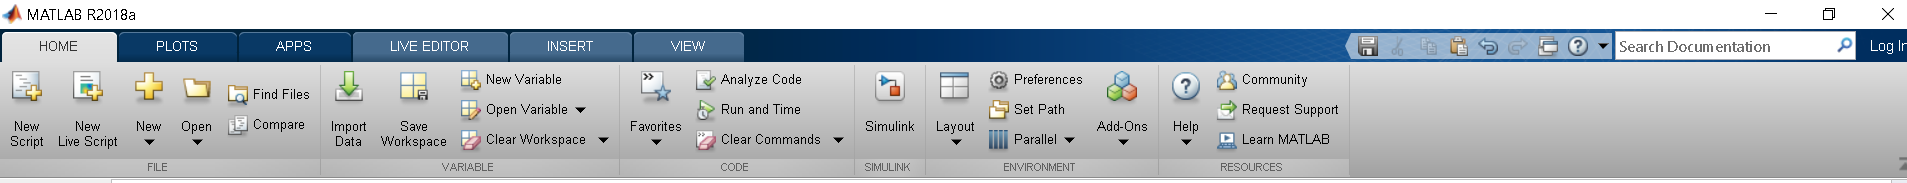

Or Help and search for function in command window

doc randi

doc randi

**Plotting **

It is important to plot the data we have for better visualization

x are the points on x axis

y are the points on y axis

**plot(x,y)**

**plot(x,y,"r--o")**

The command above plots a red (r) dashed (--) line with a circle (o) as a marker. You can learn more about the symbols available in the documentation for [Line Specification](https://www.mathworks.com/help/matlab/ref/linespec.html).

**hold on **command to hold the previous plot while you add another line

Check out : [https://in.mathworks.com/products/matlab/plot-gallery.html](https://in.mathworks.com/products/matlab/plot-gallery.html) 

Some more commands .

xlabel('-pi/2 < x < pi/2') 

ylabel('Sine and Cosine Values') 

legend(["cos" "sin"])

x=-pi/2:0.1:pi/2
y=cos(x)
z=sin(x)
plot(x,y,"b--o")
hold on
plot(x,z,"r--o")
hold off
xlabel('-pi/2<x<pi/2')
ylabel('sine and cosine values')
legend(["cos" "sin"])

[Relational operators](https://www.mathworks.com/help/matlab/matlab_prog/array-comparison-with-relational-operators.html), such as >, <, ==, and ~= perform comparisons between two values. The outcome of a comparison for equality or inequality is either 1 (true) or 0 (false).

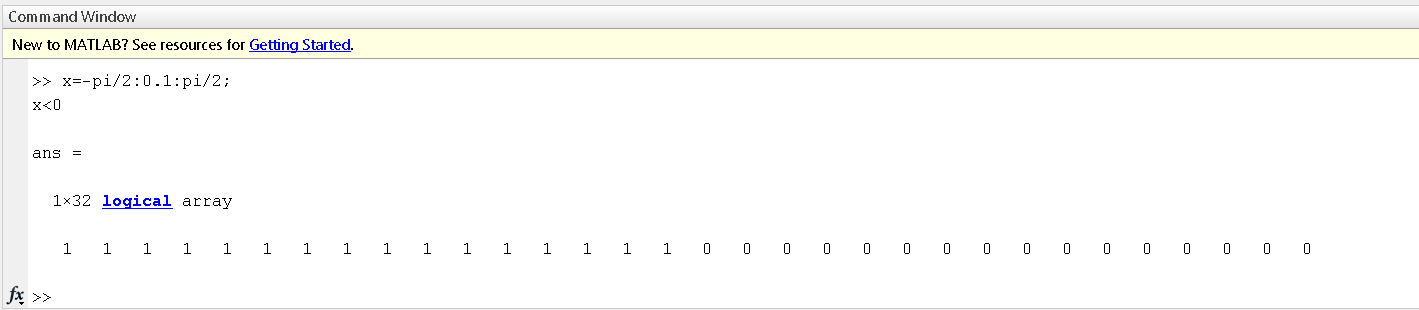

You can use a logical array as an array index, in which case MATLAB extracts the array elements where the index is true.

x(x<0)

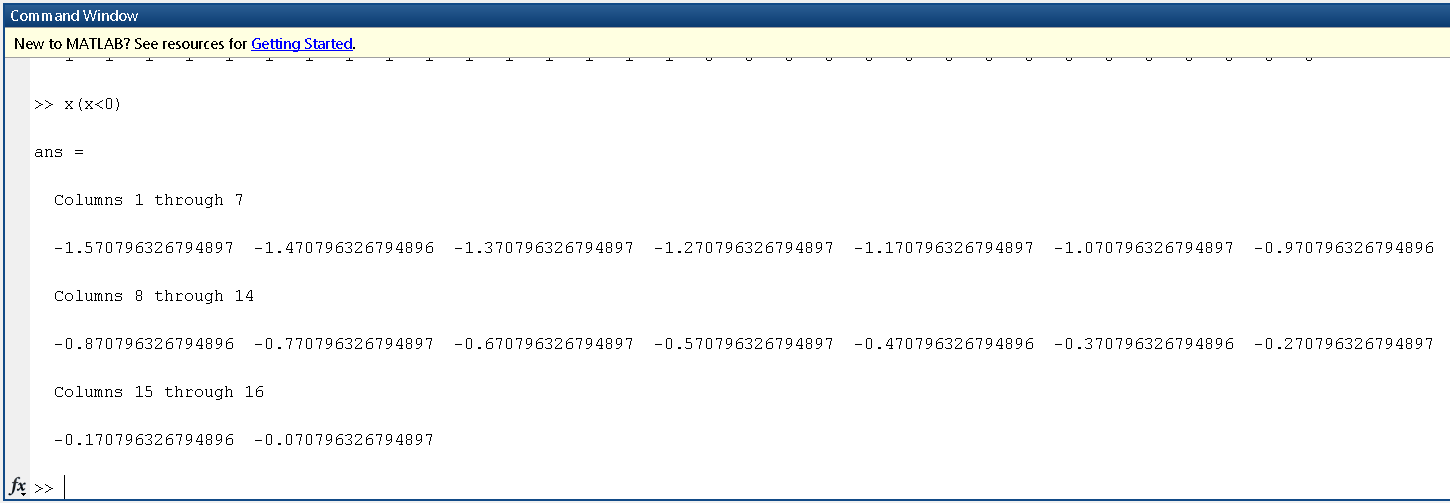

To reassign value

x(x==0) = 1

x=-pi/2:0.1:pi/2
x<0
x(x<0)

IF/ELSE

Conditional statements are required to skip a section of code if some contion is true or false

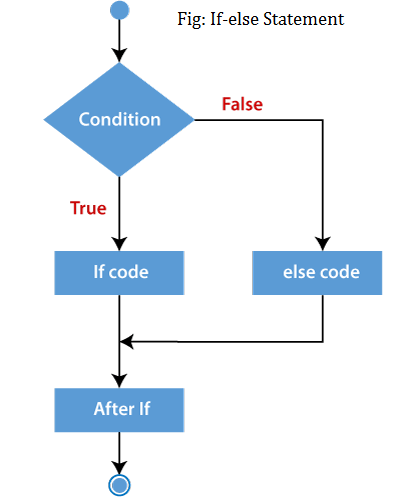

xxx

if condition

      xxx

elseif condition 

    xxx

else

xxxxxx

end

xxx

Tip: No need to worry about indentation but it is good to have

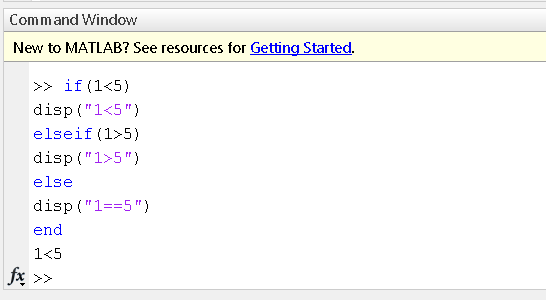

if(1<5)
disp("1<5")
elseif(1>5)
disp("1>5")
else
disp("1==5")
end

LOOP

looops are used if we want ot execute same command again and again

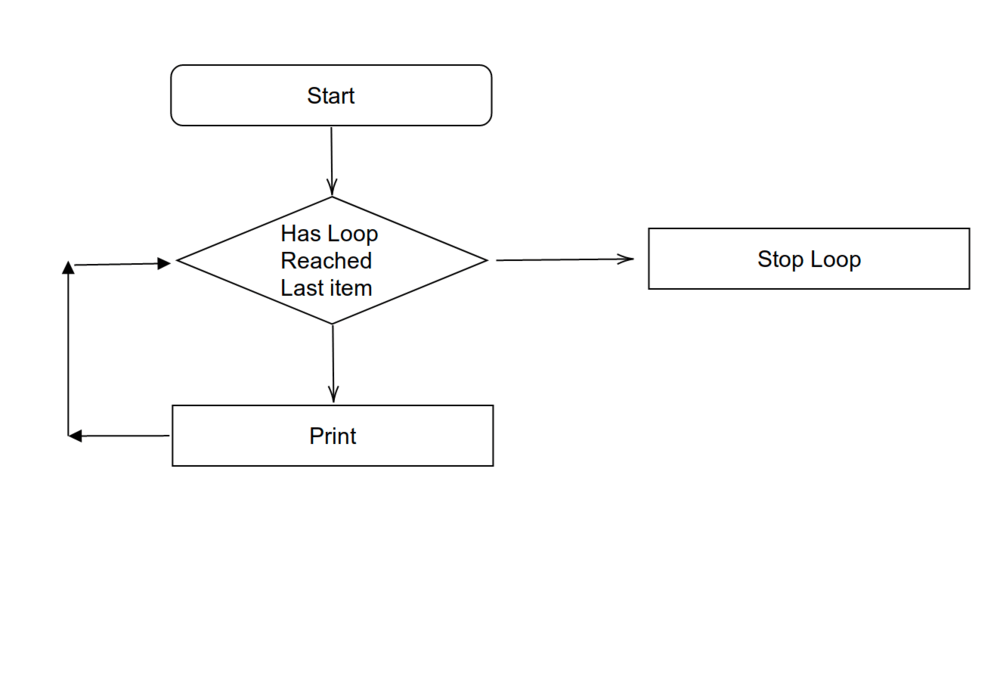

for x=1:5

xxxxx

end

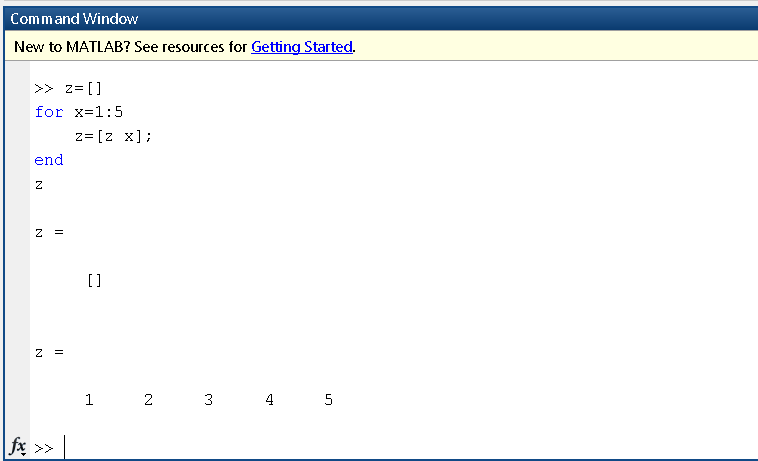

z=[]
for x=1:5
    z=[z x];
end
z